# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

1.- Operating table. It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Use 'patch' or 'fill3' functions to model it.

*Add your comemnts here..... be concise*

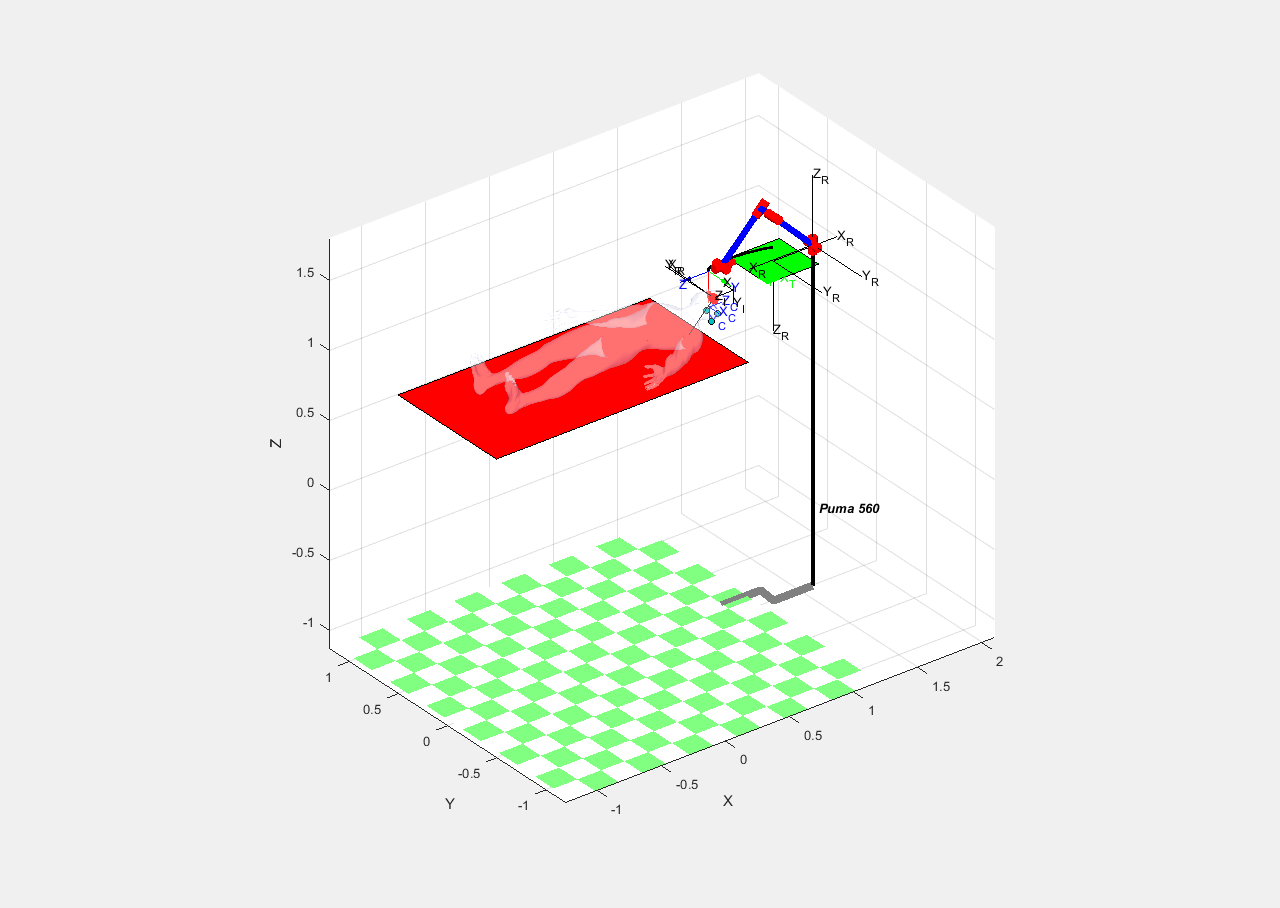

tool_offset = [0, 0, 0.1];
table_h = 1.0;
table_length = 2.5;
table_width = 1.0;
t1_x = [-table_length/2 table_length/3.5 table_length/3.5 -table_length/2];
t1_y = [-table_width/2 -table_width/2 table_width/2 table_width/2];
t1_z = [table_h table_h table_h table_h];

patch(t1_x,t1_y,t1_z,'red')

toolt_origin = [1.4 0.2 table_h];
toolt_size = [0.4 0.4 0];
t2_x = [toolt_origin(1) toolt_origin(1)+toolt_size(1) toolt_origin(1)+toolt_size(1) toolt_origin(1)];
t2_y = [toolt_origin(2) toolt_origin(2) toolt_origin(2)+toolt_size(2) toolt_origin(2)+toolt_size(2)];
t2_z = [toolt_origin(3) toolt_origin(3) toolt_origin(3) toolt_origin(3)];

patch(t2_x,t2_y,t2_z,'green')

axis([-2 2 -2 2 0 4]), axis('equal');
camlight('headlight');
material('dull');
xlabel('X'), ylabel('Y'), zlabel('Z')
hold on

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*Add your comemnts here..... be concise*

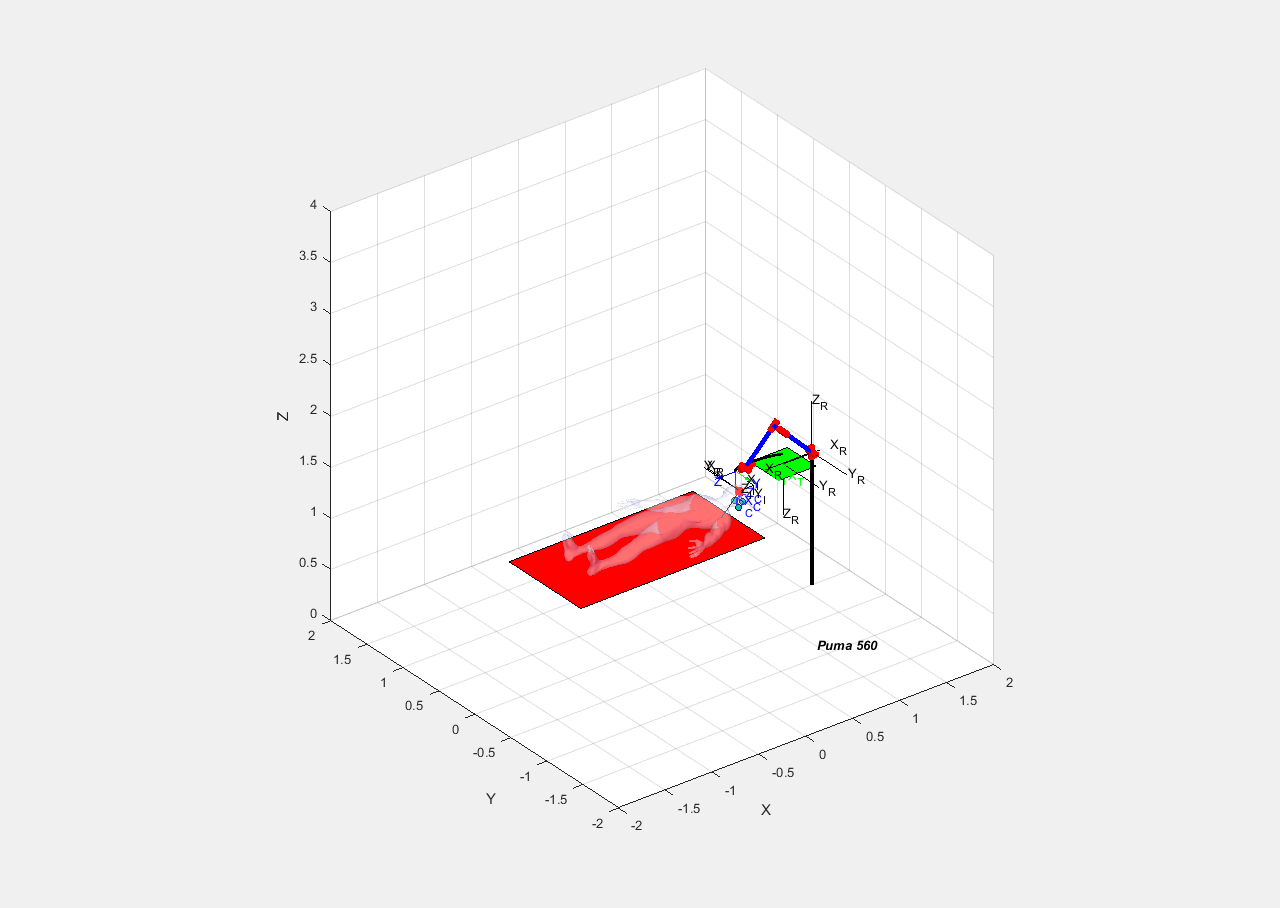

[VB,FB] = readOBJ('Human_body.obj','Quads',true);
person_height = 1.8;
VB = VB .* (person_height/max(VB(:, 2)));
VB = [VB ones(size(VB, 1), 1)];
VB = transl(-person_height/2, 0, table_h-min(VB(:, 3)))*trotz(-90, 'deg')*VB';
VB = (VB(1:3, :))';
p = patch('Faces',FB,'Vertices',VB, 'FaceColor',       [0.8 0.8 1.0], ...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15, ...
         'FaceAlpha', 0.25);
axis([-2 2 -2 2 0 4]);

3.- A human skull model, embedded in the head of the human. Place the fiducials.

*Add your comemnts here.....be concise*

## put your code Here

% [VS,FS] = stlRead('Crani.stl');
RFC = transl(person_height/2-0.11,-0.005,table_h+0.1425)*troty(90, 'deg')*trotz(-90, 'deg')*trscale(0.001);
% VS2 = h2e(RFC*e2h(VS'))';
% 
% p = patch('Faces',FS,'Vertices',VS2, 'FaceColor',       [0.2 1 0.2], ...
%          'EdgeColor',       'none',        ...
%          'FaceLighting',    'flat',     ...
%          'AmbientStrength', 0.95, ...
%          'FaceAlpha', 0.75);

RFI = RFC * trscale(1, 1, 1.4) * troty(180, 'deg') * transl(-125, -145, -65);
fiducidals = load('fiducidals.csv');
fiducidals = h2e(RFI * e2h(fiducidals'))';

scatter3(fiducidals(:, 1), fiducidals(:, 2), fiducidals(:, 3), 24, ...
    'MarkerEdgeColor','k', ...
    'MarkerFaceColor',[0 .75 .75])  

4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*Add your comemnts here.....be concise*

tumor = load('tumor.csv');


t_even = tumor(1:2:end, :);
t_odd = tumor(2:2:end, :);

t_n1 = [t_even(:, 1) t_odd(:, 2) t_even(:, 3)];
t_n2 = [t_odd(:, 1) t_even(:, 2) t_even(:, 3)];

tumor = [tumor; t_n1; t_n2];

*First approach:**  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

*Add your comemnts here.....be concise*

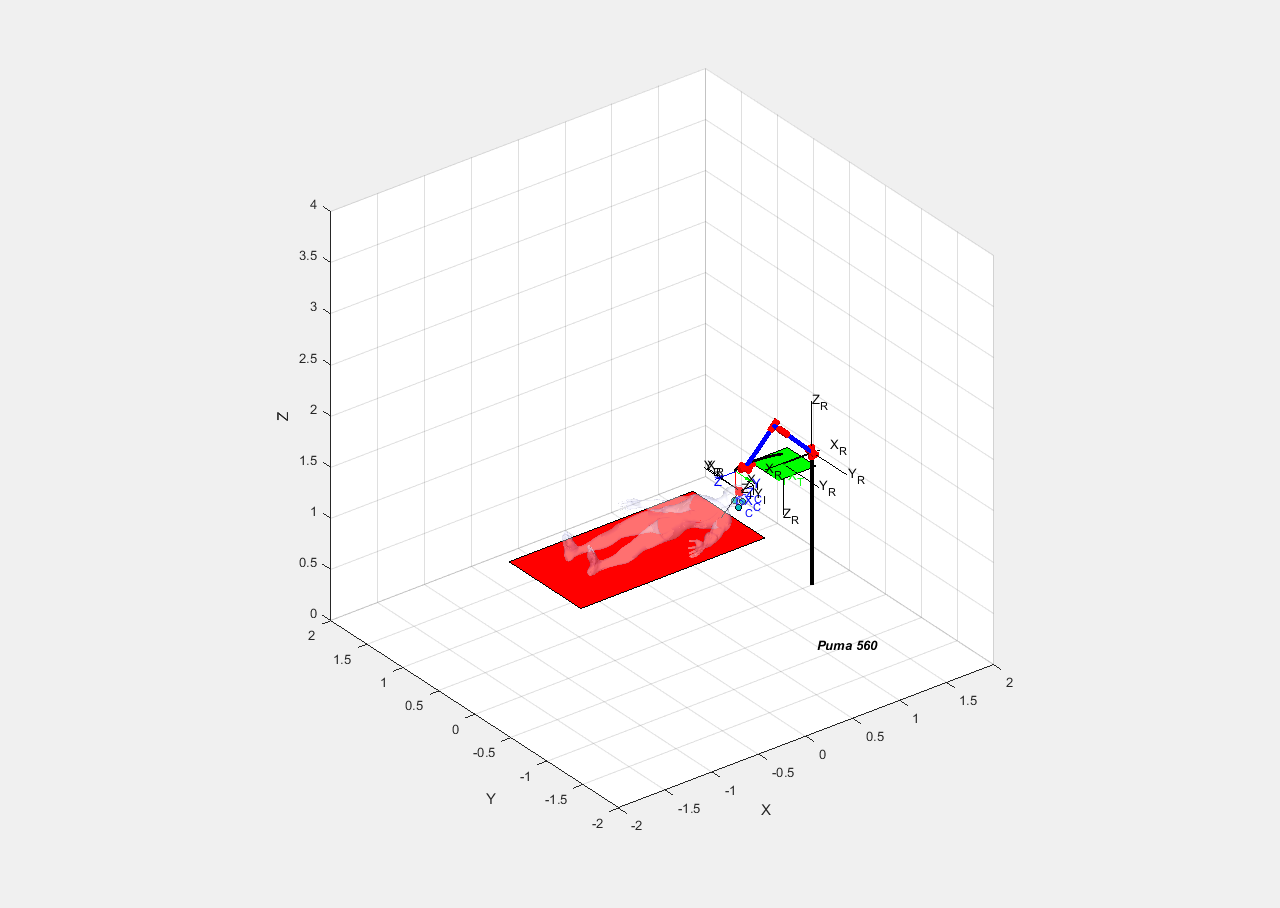

trplot(RFC, 'length', 100, 'color', 'b', 'frame', 'C')
trplot(RFI, 'length', 100, 'color', 'k', 'frame', 'I')

RFT = transl(toolt_origin);
trplot(RFT, 'length', 0.1, 'color', 'g', 'frame', 'T')

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

*Add your comemnts here.....be concise*

mdl_puma560
%EE=p560.fkine(qz)
%RFR = transl(1.6, 0, 1.2) * trotz(90, 'deg');
RFR = transl(1.6, 0, 1.3) * trotz(180, 'deg');
p560.tool = SE3(tool_offset);
p560.base = RFR;
%p560.plot(qz, 'zoom', 2)

trplot(RFR, 'length', 0.5, 'color', 'k', 'frame', 'R')

7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts here.....be concise*

% %tumor = h2e(RFI * e2h(tumor'))';
% 
% %tumor % RFI
% vIR = RFI(1:3, 4) - RFR(1:3, 4);
% rotIR = trotz(-90, 'deg') * trotx(-90, 'deg') * transl(-RFR(1:3, 4));
% %tumor_new = h2e(transl(dist) * transl(RFI(1:3, 4)) * trotz(-90, 'deg') * trotx(90, 'deg') * e2h(tumor'))'
% ItoR = transl(vIR) * rotIR
% tumorR = h2e(ItoR * e2h(tumor'))'
% tumor_new = h2e(RFR * trscale(0.001, 0.001, 0.001) * e2h(tumorR'))'

ItoR = inv(RFR) * RFI

ItoR =          0         0    0.0014    0.7190
   -0.0010         0         0    0.1300
         0   -0.0010         0   -0.0125
         0         0         0    1.0000



% pointWI = h2e(RFI * e2h(tumor'))';
pointR = h2e(ItoR * e2h(tumor'))';
pointWR = h2e(RFR * e2h(pointR'))';
tumor = pointWR;

8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

scatter3(pointWR(:, 1), pointWR(:, 2), pointWR(:, 3), 12, 'r', 'filled')

9.- Prepare a script that perform a biopsy. Zoom in the scene

*Add your comemnts here.....be concise*

% view(15, 20);
% axis([0.4, 1.2, -0.4, 0.4, 0.9, 1.7])
type task_changeTool


tool_pos = toolt_size./2;
%tool_pos(3) = tool_pos(3)+0.2;

t1 = [0:0.05:5];
t2 = [0:0.05:0.5];

tool_posW = h2e(RFT * e2h(tool_pos'))';

T_tool = transl(tool_posW) * trotz(0, 'deg') * trotx(180, 'deg');

T_tool_start = transl(0, 0, 0.1) * T_tool;
trplot(T_tool, 'length', 0.5, 'color', 'k', 'frame', 'R')

%% Trajectory 1: qn -> tool start
q_tool_start = p560.ikine6s(T_tool_start, 'run');
traj_1 = jtraj(qn, q_tool_start, t1);

p560.plot(traj_1, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)

%% Trajectory 2: tool start -> pick tool
Ts = ctraj(T_tool_start, T_tool, length(t2)); 
traj_2 = p560.ikine6s(Ts, 'run');

p560.plot(traj_2, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)

%% Trajectory 2R: pick tool -> tool start
traj_2r = flipud(traj_2);

p560.plot(traj_2r, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)

%% Trajectory 1R: pick tool -> qn
traj_1r = flipud(traj_1);

p560.plot(traj_1r, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)


type task_biopsy


tumor_center = mean(tumor(:, :));

t = [0:0.05:5]';

T_biopsy_end = transl(tumor_center) * troty(-135, 'deg');
T_biopsy_start = T_biopsy_end * transl(0, 0, -0.2);

trplot(T_biopsy_end, 'length', 0.5, 'color', 'k', 'frame', 'R')

%% Trajectory 1: qn -> biopsy start
q_biopsy_start = p560.ikine6s(T_biopsy_start, 'run');
traj_1 = jtraj(qn, q_biopsy_start, t);

p560.plot(traj_1, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)
%p560.plot3d(traj_1, 'fps', 60, 'trail', {'k', 'LineWidth', 2})

%% Trajectory 2: biopsy
Ts = ctraj(T_biopsy_start, T_biopsy_end, length(t)); 
traj_2 = p560.ikine6s(Ts, 'run');
traj_2r = flipud(traj_2);
traj_2loop = [traj_2; traj_2r];

p560.plot(traj_2loop, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)
%p560.plot3d(traj_2loop, 'fps', 60, 'trail', {'k', 'LineWidth', 2})

%% Trajectory 1R: biopsy start -> qn
traj_1r = flipud(traj_1);

p560.plot(traj_1r, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)
%p560.plot3d(traj_1r, 'fps', 60, 'trail', {'k', 'L

10.- Prepare a script that perform trepanation.

*Add your comemnts here.....be concise*

%view(15, 20);
%axis([0.4, 1.2, -0.4, 0.4, 0.9, 1.7])
type task_changeTool


tool_pos = toolt_size./2;
%tool_pos(3) = tool_pos(3)+0.2;

t1 = [0:0.05:5];
t2 = [0:0.05:0.5];

tool_posW = h2e(RFT * e2h(tool_pos'))';

T_tool = transl(tool_posW) * trotz(0, 'deg') * trotx(180, 'deg');

T_tool_start = transl(0, 0, 0.1) * T_tool;
trplot(T_tool, 'length', 0.5, 'color', 'k', 'frame', 'R')

%% Trajectory 1: qn -> tool start
q_tool_start = p560.ikine6s(T_tool_start, 'run');
traj_1 = jtraj(qn, q_tool_start, t1);

p560.plot(traj_1, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)

%% Trajectory 2: tool start -> pick tool
Ts = ctraj(T_tool_start, T_tool, length(t2)); 
traj_2 = p560.ikine6s(Ts, 'run');

p560.plot(traj_2, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)

%% Trajectory 2R: pick tool -> tool start
traj_2r = flipud(traj_2);

p560.plot(traj_2r, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)

%% Trajectory 1R: pick tool -> qn
traj_1r = flipud(traj_1);

p560.plot(traj_1r, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)


type task_trepanation


t = [0:0.05:5]';

% Radi. Ha de ser una mica més petit que el radi del tumor.
radius = compute_radius(tumor) - 0.002;
tumor_center = mean(tumor(:, :));
T_trepanation = transl(tumor_center) * transl(0.06, 0, 0) * troty(70, 'deg');

Ts_trepanation = zeros(4, 4, length(t));

%hold on;
for i=1:length(t)
    a = (t(i)/t(end))*(2*pi);
    c = [cos(a)*radius
         sin(a)*radius
         0];
    Ts_trepanation(:,:,i) = transl(c) *  trotz(a+pi)* troty(-45, 'deg') * trotx(180, 'deg');
    Ts_trepanation(:,:,i) = T_trepanation * Ts_trepanation(:,:,i);
    Ts_trepanation(:,:,i) = Ts_trepanation(:,:,i);
    %trplot(Ts_trepanation(:,:,i), 'length', 0.5, 'color', 'k')
end
%hold off;
%axis('equal');

%% Trajectory 1: qn -> trepanation pre
T_trepanation_start = Ts_trepanation(:, :, 1);
T_trepanation_pre = T_trepanation_start * transl(0, 0, -0.1);
q_trepanation_pre = p560.ikine6s(T_trepanation_pre, 'run');
traj_1 = jtraj(qn, q_trepanation_pre, t);

p560.plot(traj_1, 'fps', 60, 'trail', {'k', 'LineWi

11.- Prepare a script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

view(15, 20);
axis([0.4, 1.2, -0.4, 0.4, 0.9, 1.7])
type task_changeTool


tool_pos = toolt_size./2;
%tool_pos(3) = tool_pos(3)+0.2;

t1 = [0:0.05:5];
t2 = [0:0.05:0.5];

tool_posW = h2e(RFT * e2h(tool_pos'))';

T_tool = transl(tool_posW) * trotz(0, 'deg') * trotx(180, 'deg');

T_tool_start = transl(0, 0, 0.1) * T_tool;
trplot(T_tool, 'length', 0.5, 'color', 'k', 'frame', 'R')

%% Trajectory 1: qn -> tool start
q_tool_start = p560.ikine6s(T_tool_start, 'run');
traj_1 = jtraj(qn, q_tool_start, t1);

p560.plot(traj_1, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)

%% Trajectory 2: tool start -> pick tool
Ts = ctraj(T_tool_start, T_tool, length(t2)); 
traj_2 = p560.ikine6s(Ts, 'run');

p560.plot(traj_2, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)

%% Trajectory 2R: pick tool -> tool start
traj_2r = flipud(traj_2);

p560.plot(traj_2r, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)

%% Trajectory 1R: pick tool -> qn
traj_1r = flipud(traj_1);

p560.plot(traj_1r, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)


type task_burningLaser


% Burn the tumor with a laser tool. The hole is no necessary to be big, the surgeons forecast half
% radius of the tumor equivalent sphere. To burn the tumor, assume the tool irradiate heat like a
% sphere shape of 4mm radius. Take care not burn healthy biological tissues.
tumor = pointWR;
t = [0:0.05:5]';

[mean_radius, radiusX, radiusY, radiusZ] = compute_radius(tumor)
radiusX = radiusX * 0.7071 - 0.004; %1/sqrt(2)
radiusY = radiusY * 0.7071 - 0.004; %1/sqrt(2)
radiusZ = radiusZ * 0.7071 - 0.004; %1/sqrt(2)
% radiusX = radiusX * 1000; radiusY = radiusY * 1000; radiusZ = radiusZ * 1000;
vX = 0.004;
vY = 0.004;
vZ = 0.004;
radius = mean_radius ./ 2;
tumor_center = mean(tumor(:, :));
T_trepanation = transl(tumor_center) * transl(0.06, 0, 0) * troty(70, 'deg');

Ts_trepanation = zeros(4, 4, length(t));

diameterX = radiusX * 2;
% pointsX = zeros((ceil((diameterX*1000 - 8)/4)), 3);
% for k = 1:(ceil((diameterX*1000 - 8)/4))
%     pointsX(k, :) = tumor_center + [-radiusX+k*vX 0 0];
% end


*Second approach:**  Assume that the ZX plane of the Robot is not aligned with plane of symetry of the human body and it is needed a orientation calibration.*

12.-Get the transformation that maps tumor points in Robot Frame. See teacher help: Triangle.mlx

*Add your comemnts here.....be concise*

pointWR = h2e(RFR * e2h(pointR'))';

13.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

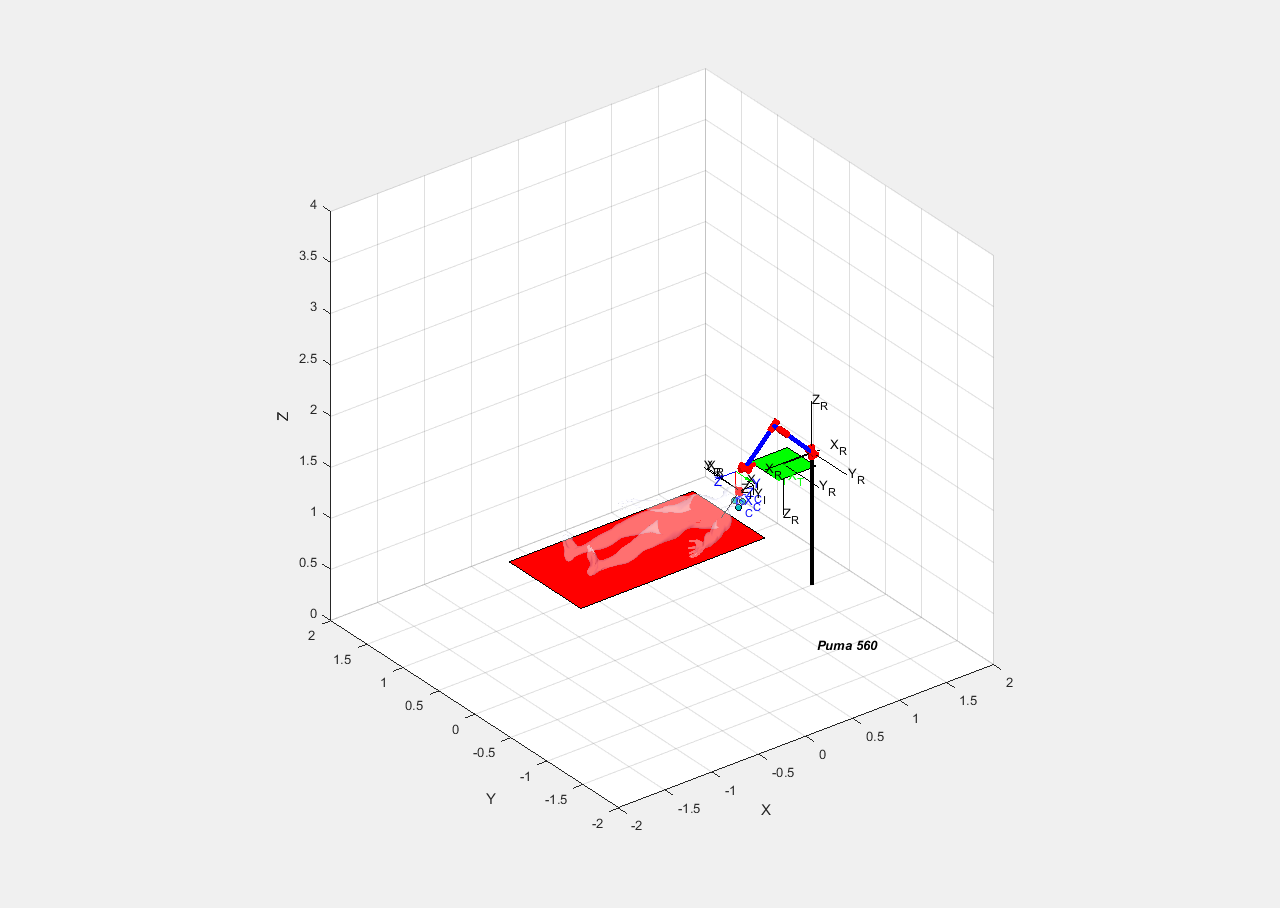

scatter3(pointWR(:, 1), pointWR(:, 2), pointWR(:, 3), 12, 'r', 'filled')

14.-Use the script that perform a biopsy. Zoom in the scene

*Add your comemnts here.....be concise*

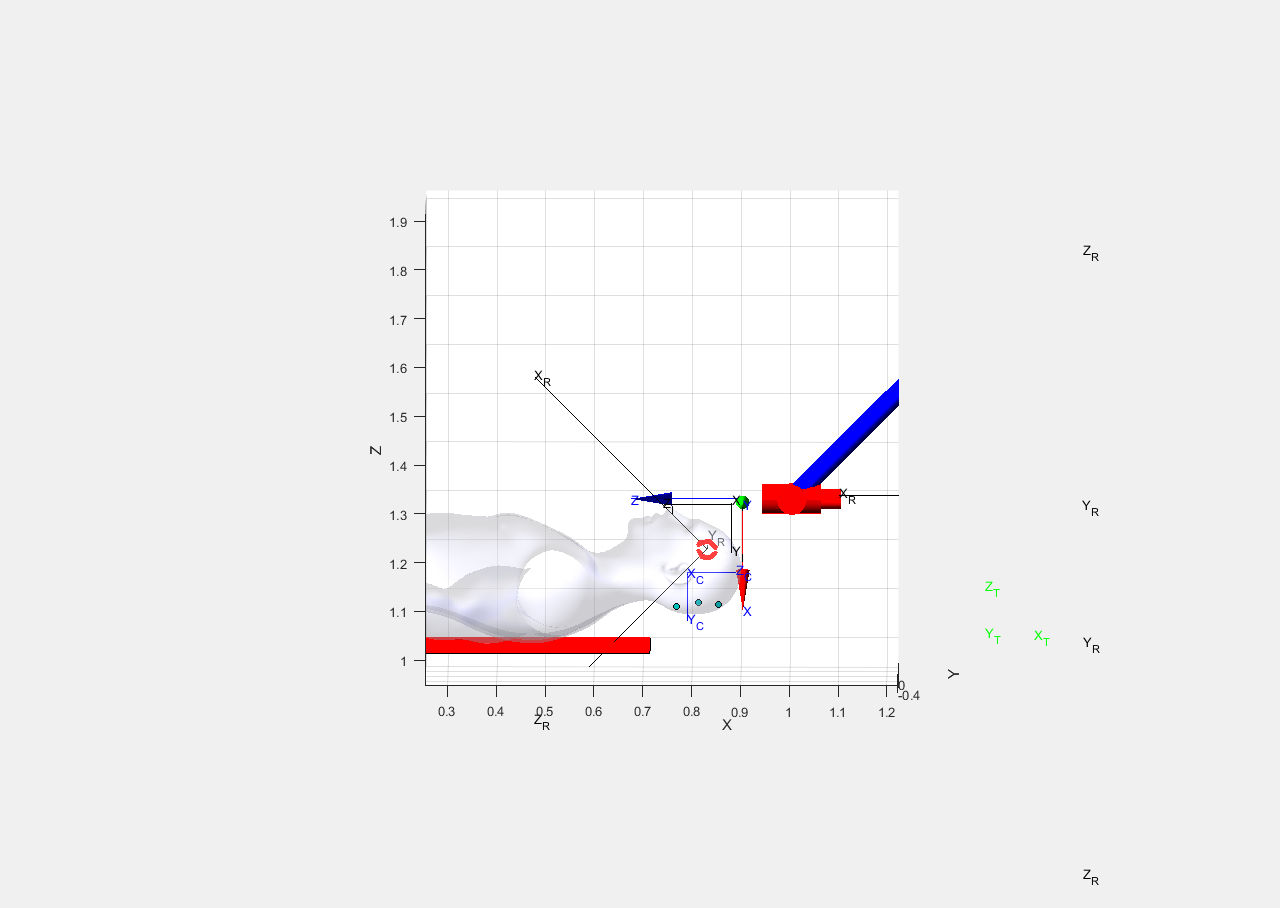

task_changeTool
task_biopsy

15.- Use the  script that perform trepanation.

*Add your comemnts here.....be concise*

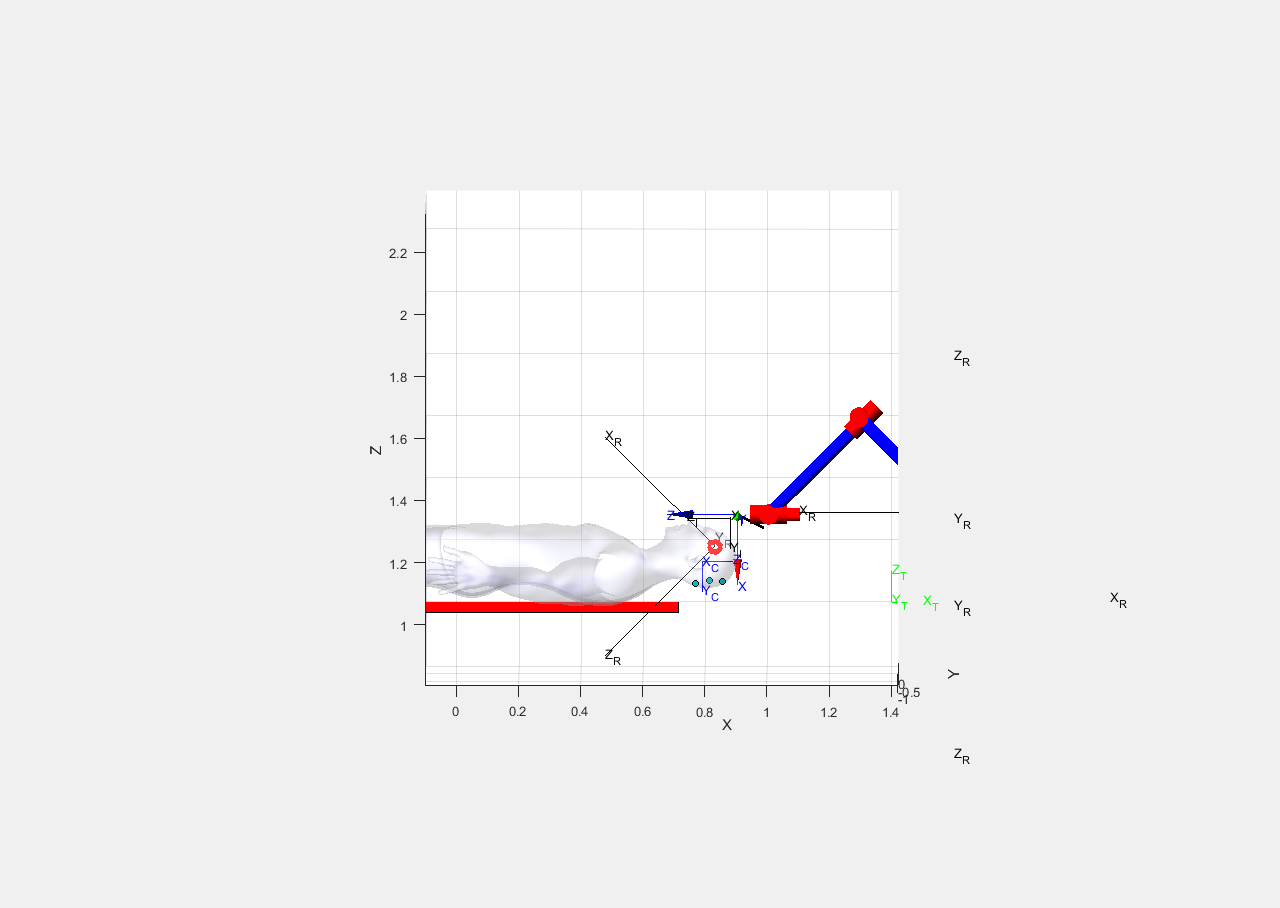

task_changeTool

task_trepanation

Undefined function or variable 'task_trpeanation'.

16.- Use the script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

task_changeTool
task_burningLaser